clear variables;

% [data,queries,gt,dataname] = get_data("DinoV2",-1);
% [data,queries,gt,dataname] = get_data("GloVe",-1);
% [data,queries,gt,dataname] = get_data("GloVe200",-1);
% [data,queries,~,dataname] = get_data("PubMed",-1);
% [data,queries,~,dataname] = get_data("Laion",-1);
% [data,queries,gt,dataname] = get_data("Wiki",-1);
[data,queries,~,dataname] = get_data("Uniform",64);
% [data,queries,gt,dataname] = get_data("Uniform",1024);
% [data,queries,gt,dataname] = get_data("Uniform",128);
% [data,queries,~,dataname] = get_data("Uniform",256);
% [data,queries,~,dataname] = get_data("Uniform",512);
% [data,queries,~,dataname] = get_data("Uniform",2048);
% [data,queries,gt,dataname] = get_data("Uniform",750);
% [data,queries,gt,dataname] = get_data("Uniform",1000);

data = data(1:100000,:);

try
    load(strcat("/Users/newrichard/git/matlab/MetricSearch/2026_rabbits/_rabbit_new_",dataname,".mat"));
catch
    disp(strcat("no data file for ",dataname));
end

rrots = getRandomRotations(size(data,2),1,0);
rrot = squeeze(rrots(1,:,:));
data = data * rrot;

queries = queries * rrot;
qDists = data * queries';
[~,gt] = maxk(qDists,201);

intraDataDists = data * data(1:1000,:)';
[~,gt_self_join] = maxk(intraDataDists,201);



tic;
tq_quants_col_major = tq_quant_dequant(data');
tq_quants = tq_quants_col_major';
toc;

Elapsed time is 0.162964 seconds.



% tq_quants = tq_quants ./ euc(zeros(1,size(tq_quants,2)),tq_quants);

% re_quants = single(rq_data(1:100000,:));
% rb_quants = rb_quants ./ euc(zeros(1,size(rb_quants,2)),rb_quants);

noOfData = size(data,1);

if ~exist("rb_quants","var")
    rq_data = zeros(noOfData,size(data,2),"int8");
    rb_goodness = zeros(noOfData,1);
    tic;
    for i = 1 : noOfData
        if mod(i,5000) == 0
            disp(i);
        end
        [rabitQ,g] = rabit2_mod(data(i,:));
        rq_data(i,:) = rabitQ;
        rb_goodness(i) = g;
    end
    toc;
    rb_centred = single(rq_data) - 1.5;
    rb_quants = rb_centred ./ euc(zeros(1,size(rb_centred,2)),rb_centred);

    save(strcat("_rabbit_new_",dataname),"rb_quants")
else
    % rb_quants = single(rb_quants);
    rb_goodness = zeros(noOfData,1);
    for i = 1 : size(data,1)
        rb_goodness(i) = data(i,:) * rb_quants(i,:)';
    end
end

% 
% rb_goodness = zeros(noOfData,1);
% for i = 1 : size(data,1)
%     rb_goodness(i) = data(i,:) * rb_quants(i,:)';
% end



% rb_quants = rb_quants_unnormed ./ euc(zeros(1,size(rb_quants,2)),rb_quants_unnormed);
% rb_goodness = zeros(size(rb_quants,1),1);
% for i = 1 : size(rb_quants,1)
%     rb_goodness(i) = data(i,:) * rb_quants(i,:)';
% end


tic;
[evp_quants,evp_goodness] = getEVP_1_2(data);
toc;

Elapsed time is 0.252762 seconds.




evp_res_hat = evp_quants * evp_quants(1:1000,:)' ./ evp_goodness ./ evp_goodness(1:1000)';
[~,evp_ord_hat] = maxk(evp_res_hat,101);

evp_res = evp_quants * queries' ./ evp_goodness;
[~,evp_ord] = maxk(evp_res,100);
% length(intersect(evp_ord(:,1),gt_self_join(:,1)));

tq_res = tq_quants * queries';
[~,tq_ord] = maxk(tq_res,100);
% length(intersect(tq_ord(:,1),gt_self_join(:,1)));

rb_res = rb_quants * queries' ./ rb_goodness;
[~,rb_ord] = maxk(rb_res,100);
length(intersect(tq_ord(:,1),gt_self_join(:,1)));

intersections = zeros(4,size(queries,1));
for i = 1 : size(queries,1)
    intersections(1,i) = length(intersect(evp_ord(:,i),gt(1:100,i)));
    intersections(2,i) = length(intersect(tq_ord(:,i),gt(1:100,i)));
    intersections(3,i) = length(intersect(rb_ord(:,i),gt(1:100,i)));
    intersections(4,i) = length(intersect(evp_ord_hat(2:end,i),gt_self_join(2:101,i)));
end
disp("evp,tq,rb,evphat")

evp,tq,rb,evphat


mean(intersections,2)

ans =    41.0130
   51.5950
   49.7490
   25.1500


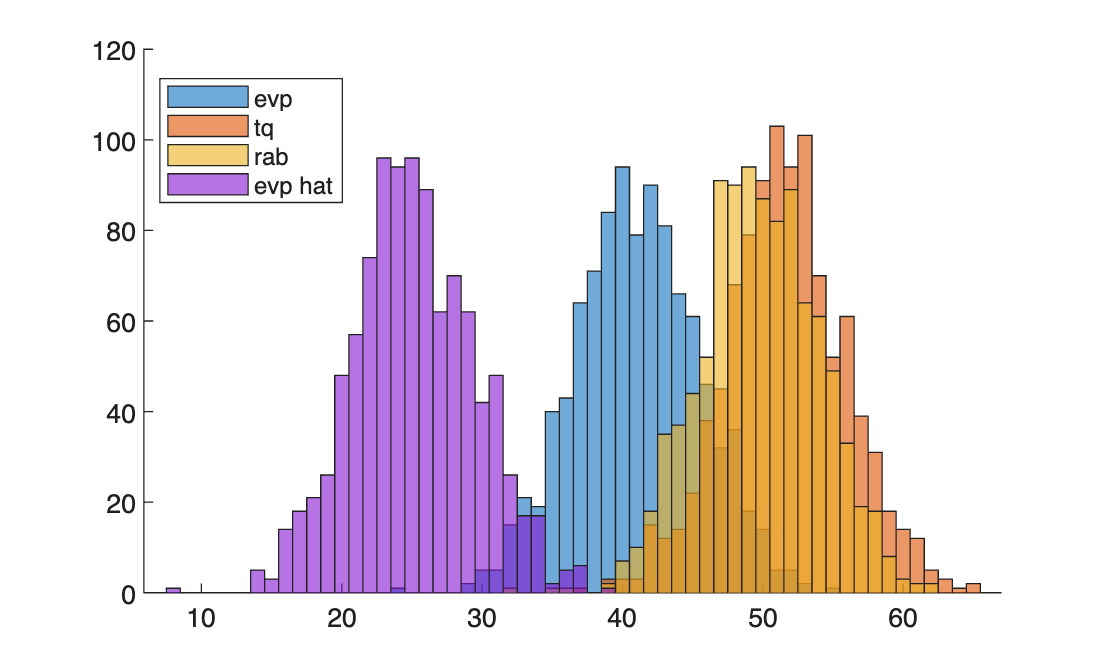


figure;
hold on;
histogram(intersections(1,:));
histogram(intersections(2,:));
histogram(intersections(3,:));
histogram(intersections(4,:));
legend("evp","tq","rab","evp hat","Location","best");

at1 = 1;
at1 = 30;
kRange = [1,2,4,8,16,32,64];
kRange = 30:100;
meanResses = zeros(4,100);

for at2 = kRange
    resses = zeros(4,1000);
    for i = 1 : size(queries,1)
        resses(1,i) = length(intersect(evp_ord(1:at2,i),gt(1:at1,i)));
        resses(2,i) = length(intersect(tq_ord(1:at2,i),gt(1:at1,i)));
        resses(3,i) = length(intersect(rb_ord(1:at2,i),gt(1:at1,i)));
        resses(4,i) = length(intersect(evp_ord_hat(2:at2+1,i),gt_self_join(2:at1+1,i)));
    end
    meanResses(:,at2) = mean(resses,2);
end

disp("evp,tq,rb,evphat")

evp,tq,rb,evphat


meanResses(:,100)

ans =    19.0180
   22.8750
   22.7520
   11.5460


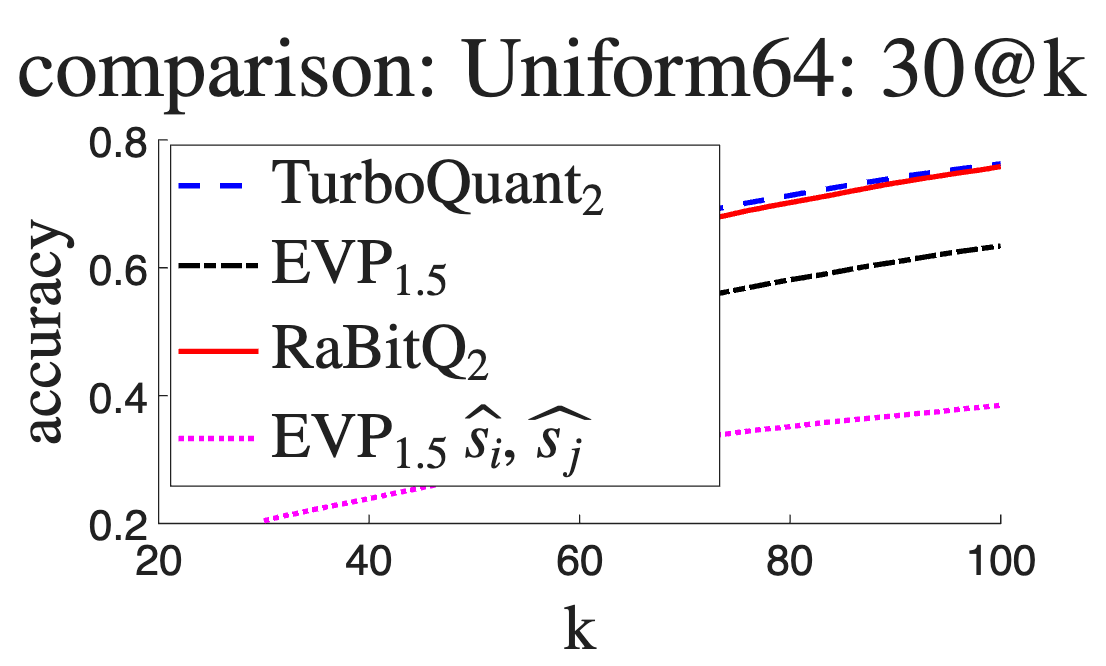


figure;
ax=gca;
ax.FontSize=16;
title(strcat("$\mathbf{q},\widehat{\mathbf{s_i}}$ comparison: ", dataname,": ",num2str(at1),"@k recall"),"Interpreter","latex",FontSize=32);
ylabel("accuracy","Interpreter","latex",FontSize=24);
xlabel("k","Interpreter","latex",FontSize=24);
hold on
plot(kRange,meanResses(2,kRange)/at1,LineWidth=2,Color="blue",LineStyle="--");
plot(kRange,meanResses(1,kRange)/at1,LineWidth=2,Color="black",LineStyle="-.");
plot(kRange,meanResses(3,kRange)/at1,LineWidth=2,Color="red",LineStyle="-");
plot(kRange,meanResses(4,kRange)/at1,LineWidth=2,Color="magenta",LineStyle=":");
legend("TurboQuant$_2","EVP$_{1.5}$","RaBitQ$_2$","EVP$_{1.5}$ $\widehat{s_i},\widehat{s_j}$","Interpreter","latex",location="best",FontSize=24);
hold off;

at1 = 1;
kRange = [1,2,4,8,16,32,64];
meanResses = zeros(4,100);

for at2 = kRange
    resses = zeros(4,1000);
    for i = 1 : size(queries,1)
        resses(1,i) = length(intersect(evp_ord(1:at2,i),gt(1:at1,i)));
        resses(2,i) = length(intersect(tq_ord(1:at2,i),gt(1:at1,i)));
        resses(3,i) = length(intersect(rb_ord(1:at2,i),gt(1:at1,i)));
        resses(4,i) = length(intersect(evp_ord_hat(2:at2+1,i),gt_self_join(2:at1+1,i)));
    end
    meanResses(:,at2) = mean(resses,2);
end

disp("evp,tq,rb,evphat")

evp,tq,rb,evphat


meanResses(:,100)

ans =      0
     0
     0
     0


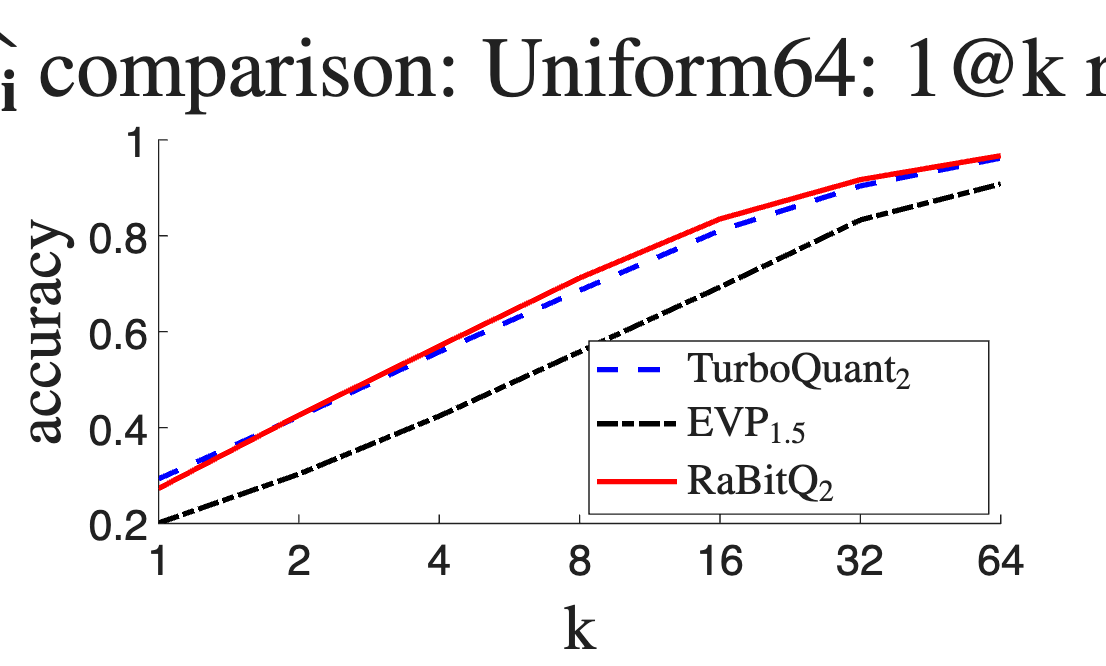

figure;
ax=gca;
ax.FontSize=16;
title(strcat("$\mathbf{q},\widehat{\mathbf{s_i}}$ comparison: ", dataname,": ",num2str(at1),"@k recall"),"Interpreter","latex",FontSize=32);
ylabel("accuracy","Interpreter","latex",FontSize=24);
xlabel("k","Interpreter","latex",FontSize=24);
xticks(0:6);
xticklabels(kRange);
hold on
plot(log2(kRange),meanResses(2,kRange)/at1,LineWidth=2,Color="blue",LineStyle="--");
plot(log2(kRange),meanResses(1,kRange)/at1,LineWidth=2,Color="black",LineStyle="-.");
plot(log2(kRange),meanResses(3,kRange)/at1,LineWidth=2,Color="red",LineStyle="-");
% plot(1:length(kRange),meanResses(4,kRange)/at1,LineWidth=2,Color="magenta",LineStyle=":");
legend("TurboQuant$_2","EVP$_{1.5}$","RaBitQ$_2$","Interpreter","latex",location="best",FontSize=16);
hold off;